%% ============================================================
%  实验名称：快速排序平均递归深度分析
%  目标：验证快速排序的平均递归深度与数据规模 N 的关系
%  理论参考：平均递归深度 ~ O(log N)
%  拟合模型：depth = a * log2(N) + b
% =============================================================

clc; clear; close all;

%% 实验数据
N = [256 512 1024 2048 4096 8192 16384 32768 65536];
depth = [13 14 17 18 20 23 24 27 29];

%% ---------- 1. 最小二乘拟合 ----------
% 拟合 y = a * log2(N) + b
x = log2(N);
p = polyfit(x, depth, 1);   % 一次多项式拟合

a = p(1);
b = p(2);

% 计算拟合值与拟合优度 R²
fit_depth = polyval(p, x);
R2 = 1 - sum((depth - fit_depth).^2) / sum((depth - mean(depth)).^2);

%% ---------- 2. 输出结果 ----------
fprintf('快速排序平均递归深度拟合结果：\n');

快速排序平均递归深度拟合结果：


fprintf('拟合方程：depth = %.4f * log2(N) + %.4f\n', a, b);

拟合方程：depth = 2.0333 * log2(N) + -3.8444


fprintf('拟合优度 R² = %.4f\n', R2);

拟合优度 R² = 0.9914


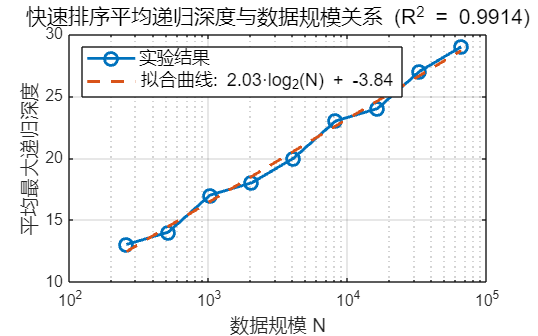


%% ---------- 3. 绘图 ----------
figure('Color','w','Position',[100 100 800 500]);

% 绘制实验点
plot(N, depth, 'o-', 'LineWidth', 1.8, 'MarkerSize', 8); hold on;

% 绘制拟合曲线
plot(N, fit_depth, '--', 'LineWidth', 1.8);

% 设置坐标为对数刻度（横轴）
set(gca, 'XScale', 'log');
xlabel('数据规模 N', 'FontSize', 12);
ylabel('平均最大递归深度', 'FontSize', 12);

% 图例与标题
legend('实验结果', sprintf('拟合曲线: %.2f·log_2(N) + %.2f', a, b), ...
    'Location','northwest', 'FontSize', 11);
title(sprintf('快速排序平均递归深度与数据规模关系 (R^2 = %.4f)', R2), 'FontSize', 13);

grid on; box on;